# Part I: Design of a function for statistical weight scoring the expected peak performance of solar panels to fully dilute the energy consumption of it. **Green SolarMiner**

## Created by Joachim Snellings

% e-mail: snellingsjoachim@hotmail.com
% Created: 25.03.2022;
% Last update: 10.01.2024

% Dayvector cycling year
dayC=[365/211:365/211:365];
% Circle Cycling vector in rad
xdata = (0:.1:2*pi)';
y0 = sin(xdata);

% Form of Pmax(y(dayC)+offset on 1 jan)
% y(t) = P(t)/Pmax sin(phi*(y0 + pi/2*T))

%Half Period Vector
xdataTfull = (0:pi/62:2*pi)';
xdataThalf = (pi/211:pi/211:pi)';

SampleWeightedDatah = [0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.56	0.56	0.56	0.56	0.56	0.56	0.56	0.54	0.54	0.54	0.54	0.54	0.54	0.54	0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.5	0.63	0.63	0.63	0.63	0.63	0.63	0.63	0.71	0.71	0.71	0.71	0.71	0.71	0.71	0.67	0.67	0.67	0.67	0.67	0.67	0.67	0.97	0.97	0.97	0.97	0.97	0.97	0.97	1.1	1.1	1.1	1.1	1.1	1.1	1.1	0.83	0.83	0.83	0.83	0.83	0.83	0.83	1.16	1.16	1.16	1.16	1.16	1.16	1.16	0.84	0.84	0.84	0.84	0.84	0.84	0.84	0.76	0.76	0.76	0.76	0.76	0.76	0.76	1.12	1.12	1.12	1.12	1.12	1.12	1.12	1.35	1.35	1.35	1.35	1.35	1.35	1.35	1.2	1.2	1.2	1.2	1.2	1.2	1.2	1.25	1.25	1.25	1.25	1.25	1.25	1.25	1.3	1.3	1.3	1.3	1.3	1.3	1.3	1.26	1.26	1.26	1.26	1.26	1.26	1.26	1.21	1.21	1.21	1.21	1.21	1.21	1.21	1.23	1.23	1.23	1.23	1.23	1.23	1.23	1.02	1.02	1.02	1.02	1.02	1.02	1.02	1.5	1.5	1.5	1.5	1.5	1.5	1.5	1.27	1.27	1.27	1.27	1.27	1.27	1.27	1.08	1.08	1.08	1.08	1.08	1.08	1.08	1.27	1.27	1.27	1.27	1.27	1.27	1.27	1.32	1.32	1.32	1.32	1.32	1.32	1.32	1.17	1.17	1.17	1.17	1.17	1.17	1.17	1.19	1.19	1.19	1.19	1.19	1.19	1.19	1.16]

SampleWeightedDatah =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5600    0.5400    0.5400    0.5400    0.5400    0.5400    0.5400    0.5400    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.6300    0.6300    0.6300    0.6300    0.6300    0.6300    0.6300    0.7100    0.7100    0.7100    0.7100    0.7100    0.7100    0.7100    0.6700


SampleWeightedDatah = SampleWeightedDatah'

SampleWeightedDatah =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5600
    0.5600
    0.5600


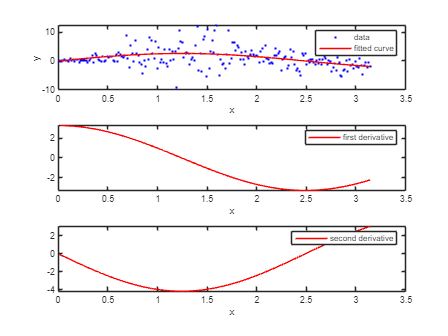


ycalc = 2.28.*sin(xdataThalf.*SampleWeightedDatah + xdataThalf./dayC');
%% 
%% 
% Add noise to the signal:
figure;
noise = 2*y0.*randn(size(y0)); % Response-dependent noise
ydata = y0 + noise;

noise = 2*ycalc.*randn(size(ycalc));
ydata = ycalc + noise;

xdata = xdataThalf;
%% 
% Fit the noisy data with a custom sinusoidal model:
f = fittype('a*sin(b*x)');
fit1 = fit(xdata,ydata,f,'StartPoint',[1 1]);


%% 
% Find the derivatives of the fit at the predictors:

[d1,d2] = differentiate(fit1,xdata);


%% 
% Plot the data, the fit, and the derivatives:

subplot(3,1,1)
plot(fit1,xdata,ydata) % cfit plot method
subplot(3,1,2)
plot(xdata,d1,'m') % double plot method
grid on
legend('1st derivative')
subplot(3,1,3)
plot(xdata,d2,'c') % double plot method
grid on
legend('2nd derivative')

%% 
% Note that derivatives can also be computed and plotted directly with the
% cfit plot method, as follows.
% The plot method, however, does not return data on the derivatives.

plot(fit1,xdata,ydata,{'fit','deriv1','deriv2'})

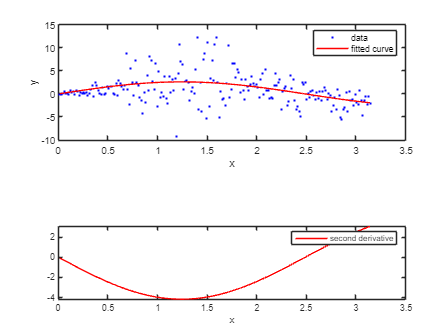


%% 
% Find the integral of the fit at the predictors:

int = integrate(fit1,xdata,0);

%% 
% Plot the data, the fit, and the integral:

subplot(2,1,1)
plot(fit1,xdata,ydata) % cfit plot method

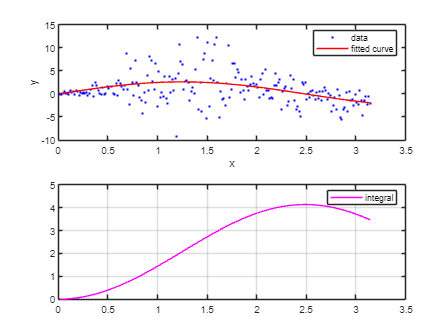

subplot(2,1,2)
plot(xdata,int,'m') % double plot method
grid on
legend('integral')

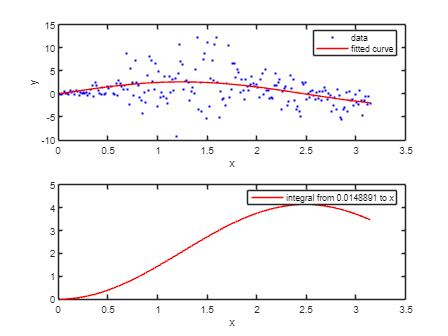


%% 
% Note that integrals can also be computed and plotted directly with the
% cfit plot method, as follows.
% The plot method, however, does not return data on the integral.

plot(fit1,xdata,ydata,{'fit','integral'})
hold off

## De variabelen in te geven



% Functie van daguur efficientie voor zonnepanelen te plannen

% reken nu 36 panelen van 460Wp die 20.3% efficient zijn en je 
% komt aan 3.625kWh per jaar gemiddeld. Met de analoge afschatting het was bewolkt op 21 december - 3.625*0.7*(5.5h*2/3+2h*2/5)=11.2

% Gemiddeld aantal vermogen opbrengst per jaar: INPUT
AantalP = 48;% [#]
Wpp = 455; %[Watt] piekvermogen 100%
EffP = 0.203 ;% [Fractional] is 100*EffP%

BaselineVerbruik = 0.380; %[kWh]
% Klopt voor situatie Marianne (Panelen 2010!?)
% AantalP = 22;% [#]
% Wpp = 170; %[Watt] piekvermogen 100%
% EffP = 0.15 ;% [Fractional] is 100*EffP%

% optioneel
RichtingPmean = [];
HoekPmean = [];

% OUTPUT - PRECALC
WppYmeanHH = Wpp*EffP*AantalP/1000*0.88;

disp(['Totaal van ' num2str(WppYmeanHH) 'kWh gemiddelde Opbrengst per uur met ' num2str(AantalP) ' Panelen aan ' num2str(Wpp) 'Wp met Efficientie ' num2str(EffP*100) '% over alle uren van een jaar.'])

Totaal van 3.9015kWh gemiddelde Opbrengst per uur met 48 Panelen aan 455Wp met Efficientie 20.3% over alle uren van een jaar.



%% hh

Headers = [{'DayIndex'}	{'Wf'}	{'WfHourCorrect'}	{'DayFraction'}	{'Licht/Donker'}];
WfOptimized = [1	0.4389	0.1432521	0.326389	0.484536082
    2	0.4392	0.1436550	0.327083	0.486068111
    3	0.4395	0.1440583	0.327778	0.487603306
    4	0.4400	0.1451389	0.329861	0.492227979
    5	0.4407	0.1456758	0.330556	0.493775934
    6	0.4414	0.1462138	0.331250	0.495327103
    7	0.4424	0.1471594	0.332639	0.498439126
    8	0.4435	0.1481413	0.334028	0.501564129
    9	0.4447	0.1491598	0.335417	0.504702194
    10	0.4460	0.1502153	0.336806	0.507853403
    11	0.4475	0.1513420	0.338194	0.511017838
    12	0.4492	0.1528528	0.340278	0.515789474
    13	0.4510	0.1537785	0.340972	0.517386723
    14	0.4529	0.1553699	0.343056	0.522198732
    15	0.4549	0.1566878	0.344444	0.525423729
    16	0.4571	0.1583978	0.346528	0.530286929
    17	0.4595	0.1598677	0.347917	0.533546326
    18	0.4620	0.1617000	0.350000	0.538461538
    19	0.4646	0.1635779	0.352083	0.54340836
    20	0.4673	0.1651776	0.353472	0.546723953
    21	0.4702	0.1671822	0.355556	0.551724138
    22	0.4732	0.1692347	0.357639	0.556756757
    23	0.4764	0.1713717	0.359722	0.561822126
    24	0.4797	0.1735581	0.361806	0.566920566
    25	0.4831	0.1757947	0.363889	0.572052402
    26	0.4866	0.1780821	0.365972	0.577217963
    27	0.4903	0.1807981	0.368750	0.584158416
    28	0.4941	0.1832288	0.370833	0.589403974
    29	0.4981	0.1857498	0.372917	0.594684385
    30	0.5021	0.1882875	0.375000	0.6
    31	0.5063	0.1912689	0.377778	0.607142857
    32	0.5106	0.1939571	0.379861	0.612541993
    33	0.5151	0.1970973	0.382639	0.619797525
    34	0.5196	0.1999017	0.384722	0.625282167
    35	0.5243	0.2028022	0.386806	0.630804077
    36	0.5291	0.2061285	0.389583	0.638225256
    37	0.5340	0.2091500	0.391667	0.643835616
    38	0.5390	0.2126056	0.394444	0.651376147
    39	0.5442	0.2161683	0.397222	0.658986175
    40	0.5494	0.2197600	0.400000	0.666666667
    41	0.5548	0.2234611	0.402778	0.674418605
    42	0.5603	0.2268437	0.404861	0.680280047
    43	0.5659	0.2302899	0.406944	0.68618267
    44	0.5716	0.2341972	0.409722	0.694117647
    45	0.5774	0.2381775	0.412500	0.70212766
    46	0.5833	0.2422315	0.415278	0.710213777
    47	0.5893	0.2463601	0.418056	0.718377088
    48	0.5954	0.2505642	0.420833	0.726618705
    49	0.6016	0.2548444	0.423611	0.734939759
    50	0.6079	0.2592018	0.426389	0.743341404
    51	0.6143	0.2632105	0.428472	0.749696233
    52	0.6208	0.2677200	0.431250	0.758241758
    53	0.6274	0.2723090	0.434028	0.766871166
    54	0.6341	0.2769784	0.436806	0.775585697
    55	0.6408	0.2821300	0.440278	0.786600496
    56	0.6477	0.2869671	0.443056	0.795511222
    57	0.6546	0.2913879	0.445139	0.802252816
    58	0.6616	0.2963417	0.447917	0.811320755
    59	0.6687	0.3013794	0.450694	0.820480405
    60	0.6759	0.3065019	0.453472	0.829733164
    61	0.6831	0.3121388	0.456944	0.841432225
    62	0.6904	0.3169128	0.459028	0.848523748
    63	0.6978	0.3222479	0.461806	0.858064516
    64	0.7053	0.3276706	0.464583	0.86770428
    65	0.7128	0.3331350	0.467361	0.877444589
    66	0.7204	0.3391883	0.470833	0.88976378
    67	0.7281	0.3443306	0.472917	0.897233202
    68	0.7358	0.3500160	0.475694	0.907284768
    69	0.7436	0.3563083	0.479167	0.92
    70	0.7514	0.3621331	0.481944	0.930294906
    71	0.7593	0.3680496	0.484722	0.940700809
    72	0.7672	0.3734772	0.486806	0.948579161
    73	0.7752	0.3800633	0.490278	0.961852861
    74	0.7832	0.3861611	0.493056	0.97260274
    75	0.7913	0.3923529	0.495833	0.983471074
    76	0.7994	0.3985897	0.498611	0.994459834
    77	0.8076	0.4049217	0.501389	1.005571031
    78	0.8158	0.4112992	0.504167	1.016806723
    79	0.8240	0.4177222	0.506944	1.028169014
    80	0.8323	0.4242418	0.509722	1.039660057
    81	0.8405	0.4307563	0.512500	1.051282051
    82	0.8489	0.4380088	0.515972	1.065997131
    83	0.8572	0.4440772	0.518056	1.074927954
    84	0.8656	0.4508333	0.520833	1.086956522
    85	0.8740	0.4582431	0.524306	1.102189781
    86	0.8824	0.4650983	0.527083	1.114537445
    87	0.8908	0.4713817	0.529167	1.123893805
    88	0.8993	0.4783776	0.531944	1.136498516
    89	0.9077	0.4859977	0.535417	1.152466368
    90	0.9162	0.4924575	0.537500	1.162162162
    91	0.9246	0.4995408	0.540278	1.175226586
    92	0.9331	0.5073731	0.543750	1.191780822
    93	0.9416	0.5146106	0.546528	1.205206738
    94	0.9501	0.5212354	0.548611	1.215384615
    95	0.9585	0.5291719	0.552083	1.23255814
    96	0.9670	0.5365507	0.554861	1.24648986
    97	0.9755	0.5439767	0.557639	1.260596546
    98	0.9839	0.5507107	0.559722	1.271293375
    99	0.9923	0.5588578	0.563194	1.289348172
    100	1.0008	0.5664250	0.565972	1.304
    101	1.0092	0.5732817	0.568056	1.31511254
    102	1.0175	0.5808229	0.570833	1.330097087
    103	1.0259	0.5891801	0.574306	1.349102773
    104	1.0342	0.5968196	0.577083	1.36453202
    105	1.0425	0.6037813	0.579167	1.376237624
    106	1.0508	0.6115072	0.581944	1.392026578
    107	1.0591	0.6192793	0.584722	1.408026756
    108	1.0673	0.6270388	0.587500	1.424242424
    109	1.0754	0.6347847	0.590278	1.440677966
    110	1.0836	0.6426350	0.593056	1.457337884
    111	1.0917	0.6504713	0.595833	1.474226804
    112	1.0997	0.6575290	0.597917	1.487046632
    113	1.1077	0.6653892	0.600694	1.504347826
    114	1.1157	0.6732940	0.603472	1.521891419
    115	1.1236	0.6804022	0.605556	1.535211268
    116	1.1314	0.6882683	0.608333	1.553191489
    117	1.1392	0.6961778	0.611111	1.571428571
    118	1.1469	0.7032727	0.613194	1.585278276
    119	1.1546	0.7112015	0.615972	1.6039783
    120	1.1622	0.7191113	0.618750	1.62295082
    121	1.1698	0.7270632	0.621528	1.642201835
    122	1.1773	0.7341774	0.623611	1.656826568
    123	1.1847	0.7420829	0.626389	1.676579926
    124	1.1920	0.7499667	0.629167	1.696629213
    125	1.1993	0.7570581	0.631250	1.711864407
    126	1.2065	0.7649545	0.634028	1.732447818
    127	1.2136	0.7719844	0.636111	1.748091603
    128	1.2206	0.7789801	0.638194	1.763915547
    129	1.2276	0.7868575	0.640972	1.785299807
    130	1.2345	0.7938521	0.643056	1.80155642
    131	1.2413	0.8008109	0.645139	1.818003914
    132	1.2480	0.8086000	0.647917	1.840236686
    133	1.2546	0.8146188	0.649306	1.851485149
    134	1.2611	0.8223423	0.652083	1.874251497
    135	1.2676	0.8292217	0.654167	1.891566265
    136	1.2739	0.8359969	0.656250	1.909090909
    137	1.2801	0.8427325	0.658333	1.926829268
    138	1.2863	0.8494940	0.660417	1.944785276
    139	1.2923	0.8552513	0.661806	1.95687885
    140	1.2983	0.8628285	0.664583	1.98136646
    141	1.3041	0.8684944	0.665972	1.993762994
    142	1.3098	0.8750192	0.668056	2.012552301
    143	1.3155	0.8815677	0.670139	2.031578947
    144	1.3210	0.8870882	0.671528	2.044397463
    145	1.3264	0.8934778	0.673611	2.063829787
    146	1.3317	0.8988975	0.675000	2.076923077
    147	1.3369	0.9042643	0.676389	2.090128755
    148	1.3420	0.9105097	0.678472	2.110151188
    149	1.3469	0.9157049	0.679861	2.123644252
    150	1.3518	0.9209138	0.681250	2.137254902
    151	1.3565	0.9259997	0.682639	2.150984683
    152	1.3611	0.9310302	0.684028	2.164835165
    153	1.3656	0.9360050	0.685417	2.178807947
    154	1.3699	0.9399036	0.686111	2.185840708
    155	1.3833	0.9509844	0.687500	2.2
    156	1.3871	0.9555233	0.688889	2.214285714
    157	1.3908	0.9590380	0.689583	2.22147651
    158	1.3943	0.9634226	0.690972	2.235955056
    159	1.3977	0.9667425	0.691667	2.243243243
    160	1.4010	0.9709708	0.693056	2.257918552
    161	1.4042	0.9741291	0.693750	2.265306122
    162	1.4072	0.9771875	0.694444	2.272727273
    163	1.4101	0.9801806	0.695139	2.280182232
    164	1.4128	0.9830733	0.695833	2.287671233
    165	1.4154	0.9848825	0.695833	2.287671233
    166	1.4179	0.9885914	0.697222	2.302752294
    167	1.4203	0.9902299	0.697222	2.302752294
    168	1.4224	0.9927167	0.697917	2.310344828
    169	1.4245	0.9941823	0.697917	2.310344828
    170	1.4264	0.9955083	0.697917	2.310344828
    171	1.4282	0.9967297	0.697917	2.310344828
    172	1.4298	0.9978813	0.697917	2.310344828
    173	1.4313	0.9989281	0.697917	2.310344828
    174	1.4327	0.9998703	0.697917	2.310344828
    175	1.4339	0.9997469	0.697222	2.302752294
    176	1.4350	1.0004790	0.697222	2.302752294
    177	1.4359	1.0011414	0.697222	2.302752294
    178	1.4367	1.0007015	0.696528	2.295194508
    179	1.4374	1.0011542	0.696528	2.295194508
    180	1.4378	1.0004692	0.695833	2.287671233
    181	1.4382	0.9987500	0.694444	2.272727273
    182	1.4384	0.9988889	0.694444	2.272727273
    183	1.4385	0.9979594	0.693750	2.265306122
    184	1.4384	0.9958922	0.692361	2.250564334
    185	1.4382	0.9947550	0.691667	2.243243243
    186	1.4378	0.9934799	0.690972	2.235955056
    187	1.4374	0.9921708	0.690278	2.228699552
    188	1.4367	0.9897267	0.688889	2.2143
    189	1.4359	0.9871813	0.687500	2.2
    190	1.4350	0.9855316	0.686806	2.192904656
    191	1.4339	0.9828190	0.685417	2.1788
    192	1.4327	0.9799724	0.684028	2.164835165
    193	1.4313	0.9770610	0.682639	2.150984683
    194	1.4298	0.9730583	0.680556	2.130434783
    195	1.4282	0.9699519	0.679167	2.116883117
    196	1.4264	0.9667822	0.677778	2.103448276
    197	1.4245	0.9635160	0.676389	2.090128755
    198	1.4224	0.9601200	0.675000	2.076923077
    199	1.4203	0.9557099	0.672917	2.057324841
    200	1.4179	0.9521592	0.671528	2.044397463
    201	1.4154	0.9485146	0.670139	2.031578947
    202	1.4128	0.9428478	0.667361	2.006263048
    203	1.4101	0.9390541	0.665972	1.993762994
    204	1.4072	0.9351684	0.664583	1.98136646
    205	1.4042	0.9292743	0.661806	1.95687885
    206	1.4010	0.9252438	0.660417	1.944785276
    207	1.3977	0.9191819	0.657639	1.920892495
    208	1.3943	0.9150094	0.656250	1.909090909
    209	1.3908	0.9088165	0.653472	1.885771543
    210	1.3871	0.9044722	0.652083	1.874251497
    211	1.3833	0.8981519	0.649306	1.851485149
    212	1.3699	0.8875810	0.647917	1.840236686
    213	1.3656	0.8810017	0.645139	1.818003914
    214	1.3611	0.8752629	0.643056	1.80155642
    215	1.3565	0.8685368	0.640278	1.77992278
    216	1.3518	0.8636500	0.638889	1.769230769
    217	1.3469	0.8567781	0.636111	1.748091603
    218	1.3420	0.8499333	0.633333	1.727272727
    219	1.3369	0.8439181	0.631250	1.711864407
    220	1.3317	0.8369365	0.628472	1.691588785
    221	1.3264	0.8317633	0.627083	1.681564246
    222	1.3210	0.8247076	0.624306	1.661737523
    223	1.3155	0.8176198	0.621528	1.642201835
    224	1.3098	0.8113483	0.619444	1.627737226
    225	1.3041	0.8041950	0.616667	1.608695652
    226	1.2983	0.7979135	0.614583	1.594594595
    227	1.2923	0.7906363	0.611806	1.576028623
    228	1.2863	0.7833924	0.609028	1.557726465
    229	1.2801	0.7769496	0.606944	1.544169611
    230	1.2739	0.7696479	0.604167	1.526315789
    231	1.2676	0.7623206	0.601389	1.508710801
    232	1.2611	0.7549085	0.598611	1.491349481
    233	1.2546	0.7475325	0.595833	1.474226804
    234	1.2480	0.7401333	0.593056	1.457337884
    235	1.2413	0.7335738	0.590972	1.444821732
    236	1.2345	0.7261260	0.588194	1.428330523
    237	1.2276	0.7195100	0.586111	1.416107383
    238	1.2206	0.7111690	0.582639	1.396006656
    239	1.2136	0.7037194	0.579861	1.380165289
    240	1.2065	0.6970889	0.577778	1.368421053
    241	1.1993	0.6895975	0.575000	1.352941176
    242	1.1920	0.6820889	0.572222	1.337662338
    243	1.1847	0.6746208	0.569444	1.322580645
    244	1.1773	0.6671367	0.566667	1.307692308
    245	1.1698	0.6596372	0.563889	1.292993631
    246	1.1622	0.6521233	0.561111	1.278481013
    247	1.1546	0.6446517	0.558333	1.264150943
    248	1.1469	0.6379631	0.556250	1.253521127
    249	1.1392	0.6305156	0.553472	1.239502333
    250	1.1314	0.6222700	0.550000	1.222222222
    251	1.1236	0.6156392	0.547917	1.211981567
    252	1.1157	0.6082115	0.545139	1.198473282
    253	1.1077	0.6000042	0.541667	1.181818182
    254	1.0997	0.5933798	0.539583	1.171945701
    255	1.0917	0.5860306	0.536806	1.15892054
    256	1.0836	0.5786725	0.534028	1.146050671
    257	1.0754	0.5713063	0.531250	1.133333333
    258	1.0673	0.5640384	0.528472	1.120765832
    259	1.0591	0.5567630	0.525694	1.108345534
    260	1.0508	0.5494808	0.522917	1.096069869
    261	1.0425	0.5422448	0.520139	1.083936324
    262	1.0342	0.5350549	0.517361	1.071942446
    263	1.0259	0.5279110	0.514583	1.060085837
    264	1.0175	0.5207622	0.511806	1.048364154
    265	1.0092	0.5137108	0.509028	1.036775106
    266	1.0008	0.5066550	0.506250	1.025316456
    267	0.9923	0.4989064	0.502778	1.011173184
    268	0.9839	0.4926333	0.500694	1.002781641
    269	0.9755	0.4857177	0.497917	0.991701245
    270	0.9670	0.4781278	0.494444	0.978021978
    271	0.9585	0.4719281	0.492361	0.969904241
    272	0.9501	0.4651531	0.489583	0.959183673
    273	0.9416	0.4577222	0.486111	0.945945946
    274	0.9331	0.4516463	0.484028	0.938088829
    275	0.9246	0.4449638	0.481250	0.927710843
    276	0.9162	0.4383763	0.478472	0.917443409
    277	0.9077	0.4317878	0.475694	0.907284768
    278	0.8993	0.4252940	0.472917	0.897233202
    279	0.8908	0.4187997	0.470139	0.887287025
    280	0.8824	0.4123994	0.467361	0.877444589
    281	0.8740	0.4060458	0.464583	0.86770428
    282	0.8656	0.3997389	0.461806	0.858064516
    283	0.8572	0.3940739	0.459722	0.850899743
    284	0.8489	0.3873106	0.456250	0.83908046
    285	0.8405	0.3811434	0.453472	0.829733164
    286	0.8323	0.3751130	0.450694	0.820480405
    287	0.8240	0.3696556	0.448611	0.813602015
    288	0.8158	0.3637108	0.445833	0.804511278
    289	0.8076	0.3572508	0.442361	0.793275218
    290	0.7994	0.3514029	0.439583	0.784386617
    291	0.7913	0.3461938	0.437500	0.777777778
    292	0.7832	0.3404744	0.434722	0.769041769
    293	0.7752	0.3348433	0.431944	0.760391198
    294	0.7672	0.3292567	0.429167	0.751824818
    295	0.7593	0.3242844	0.427083	0.745454545
    296	0.7514	0.3188232	0.424306	0.737032569
    297	0.7436	0.3134481	0.421528	0.728691477
    298	0.7358	0.3081163	0.418750	0.720430108
    299	0.7281	0.3028694	0.415972	0.712247325
    300	0.7204	0.2981656	0.413889	0.706161137
    301	0.7128	0.2930400	0.411111	0.698113208
    302	0.7053	0.2879975	0.408333	0.690140845
    303	0.6978	0.2829967	0.405556	0.682242991
    304	0.6904	0.2780778	0.402778	0.674418605
    305	0.6831	0.2737144	0.400694	0.668597914
    306	0.6759	0.2689519	0.397917	0.660899654
    307	0.6687	0.2642294	0.395139	0.653272101
    308	0.6616	0.2600456	0.393056	0.647597254
    309	0.6546	0.2554758	0.390278	0.640091116
    310	0.6477	0.2514335	0.388194	0.634506243
    311	0.6408	0.2469750	0.385417	0.627118644
    312	0.6341	0.2430717	0.383333	0.621621622
    313	0.6274	0.2387606	0.380556	0.614349776
    314	0.6208	0.2349556	0.378472	0.608938547
    315	0.6143	0.2312157	0.376389	0.603563474
    316	0.6079	0.2271182	0.373611	0.596452328
    317	0.6016	0.2235111	0.371528	0.591160221
    318	0.5954	0.2199672	0.369444	0.585903084
    319	0.5893	0.2164859	0.367361	0.580680571
    320	0.5833	0.2130665	0.365278	0.575492341
    321	0.5774	0.2093075	0.362500	0.568627451
    322	0.5716	0.2060142	0.360417	0.563517915
    323	0.5659	0.2031738	0.359028	0.560130011
    324	0.5603	0.1999960	0.356944	0.555075594
    325	0.5548	0.1964917	0.354167	0.548387097
    326	0.5494	0.1938161	0.352778	0.545064378
    327	0.5442	0.1908479	0.350694	0.540106952
    328	0.5390	0.1879014	0.348611	0.535181237
    329	0.5340	0.1854167	0.347222	0.531914894
    330	0.5291	0.1826130	0.345139	0.527041357
    331	0.5243	0.1802281	0.343750	0.523809524
    332	0.5196	0.1778908	0.342361	0.520591341
    333	0.5151	0.1756348	0.340972	0.517386723
    334	0.5106	0.1730367	0.338889	0.512605042
    335	0.5063	0.1708763	0.337500	0.509433962
    336	0.5021	0.1687614	0.336111	0.506276151
    337	0.4981	0.1667251	0.334722	0.503131524
    338	0.4941	0.1650431	0.334028	0.501564129
    339	0.4903	0.1627524	0.331944	0.496881497
    340	0.4866	0.1611863	0.331250	0.495327103
    341	0.4831	0.1593559	0.329861	0.492227979
    342	0.4797	0.1579013	0.329167	0.49068323
    343	0.4764	0.1561533	0.327778	0.487603306
    344	0.4732	0.1547758	0.327083	0.486068111
    345	0.4702	0.1531415	0.325694	0.483007209
    346	0.4673	0.1518725	0.325000	0.481481481
    347	0.4646	0.1506724	0.324306	0.47995889
    348	0.4620	0.1495083	0.323611	0.478439425
    349	0.4595	0.1483802	0.322917	0.476923077
    350	0.4571	0.1479226	0.323611	0.478439425
    351	0.4549	0.1468948	0.322917	0.476923077
    352	0.4529	0.1459344	0.322222	0.475409836
    353	0.4510	0.1453222	0.322222	0.475409836
    354	0.4492	0.1447422	0.322222	0.475409836
    355	0.4475	0.1438837	0.321528	0.473899693
    356	0.4460	0.1437111	0.322222	0.475409836
    357	0.4447	0.1429834	0.321528	0.473899693
    358	0.4435	0.1429056	0.322222	0.475409836
    359	0.4424	0.1428583	0.322917	0.476923077
    360	0.4414	0.1422289	0.322222	0.475409836
    361	0.4407	0.1423094	0.322917	0.476923077
    362	0.4400	0.1423889	0.323611	0.478439425
    363	0.4395	0.1425323	0.324306	0.47995889
    364	0.4392	0.1427400	0.325000	0.481481481
    365	0.4389	0.1429473	0.325694	0.483007209
    ];

figure;

% [{'DayIndex'}	{'Wf'}	{'WfHourCorrect'}	{'DayFraction'}	{'Licht/Donker'}]
TWfOpti.Properties.VariableNames = {'DayIndex' 'Wf' 'WfHourCorrect'	'DayFraction' 'Licht/Donker'};
TWfOpti = table(WfOptimized(:,1),WfOptimized(:,2),WfOptimized(:,3),WfOptimized(:,4),WfOptimized(:,5), 'VariableNames', {'DayIndex', 'Wf', 'WfHourCorrect' , 'DayFraction' , 'Licht/Donker'});


summary(TWfOpti)

Variables:

    DayIndex: 365×1 double

        Values:

            Min           1   
            Median      183   
            Max         365   

    Wf: 365×1 double

        Values:

            Min        0.4389 
            Median     0.9331 
            Max        1.4385 

    WfHourCorrect: 365×1 double

        Values:

            Min       0.14223 
            Median    0.47813 
            Max        1.0012 

    DayFraction: 365×1 double

        Values:

            Min       0.32153 
            Median     0.5125 
            Max       0.69792 

    Licht/Donker: 365×1 double

        Values:

            Min        0.4739 
            Median     1.0513 
            Max        2.3103 




SumWfDD = sum(TWfOpti.Wf);
SumWfHH = sum(TWfOpti.WfHourCorrect);

VerwachteDagOpbrengst = (TWfOpti.WfHourCorrect ./ SumWfHH)*WppYmeanHH*365*24;

VerwachteDagOpbrengst =    25.6798
   25.7520
   25.8243
   26.0180
   26.1143
   26.2107
   26.3802
   26.5562
   26.7388
   26.9280


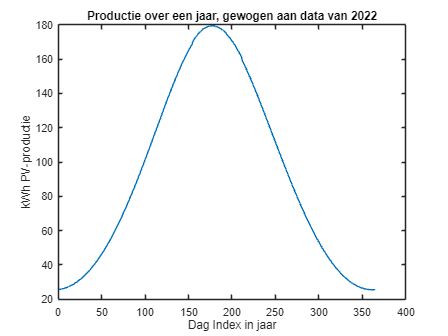

plot(TWfOpti.DayIndex,VerwachteDagOpbrengst,'DisplayName','Productieafschatting')
title('Productie over een jaar, gewogen aan data van 2022')
ylabel('kWh PV-productie')
xlabel('Dag Index in jaar')


% InvloedFactoren
Bewolking = 0.27;

DayI = TWfOpti.DayIndex;

% Pdayly = repmat(VerwachteDagOpbrengst' , [size(VerwachteDagOpbrengst) 1]);
% iw(Pdayly)
% 
% figure;
% Pmean0 =  mean(Pdayly,1);
% plot(DayI',Pmean0,'m', 'DisplayName','Pmean0')
% Pup = Pmean0 + std(Pdayly,0,1).*Pmean0.*1.15;
% Pdown = Pmean0 - std(Pdayly,0,1);
% 
% patch([DayI',fliplr(DayI')],[Pdown,fliplr(Pup)],'b','FaceAlpha',.3,'edgecolor','none')


WinterMiD = 0.618;
WinterSunSD = pi/10;
SummerMiD = 3.236;
SummerSunSD = 1.618;

EquilibrDaysMid = 1.618;
EquilibrDaysSD = 0.618;
% Schattende Factoren - FYI

## Integration of day Weighting Factors

% 16.5h licht - 7.5h donker
ZomerPiek = WppYmeanHH*Bewolking*(14.5*SummerMiD+2*SummerSunSD);
% 7.5h licht - 16.5h donker
WinterPiek = WppYmeanHH*Bewolking*(5.5*WinterMiD+2*WinterSunSD);

MidyearPiek = WppYmeanHH*Bewolking*(10*EquilibrDaysMid+2*EquilibrDaysSD);

disp(['Totaal van ' num2str(WinterPiek) 'kWh gemiddelde dag Opbrengst met Bewolking en ' num2str(WinterPiek/0.7) 'kWh indien zonnige dag op 21 December'])

Totaal van 4.2424kWh gemiddelde dag Opbrengst met Bewolking en 6.0606kWh indien zonnige dag op 21 December


disp(['Totaal van ' num2str(ZomerPiek) 'kWh gemiddelde dag Opbrengst met Bewolking en ' num2str(ZomerPiek/0.7) ' kWh indien zonnige dag op 21 Juni'])

Totaal van 52.8367kWh gemiddelde dag Opbrengst met Bewolking en 75.4809 kWh indien zonnige dag op 21 Juni


disp(['Totaal van ' num2str(MidyearPiek) 'kWh gemiddelde dag Opbrengst met Bewolking en ' num2str(MidyearPiek/0.7) ' kWh indien zonnige dag op 21 Maart/September'])

Totaal van 18.3461kWh gemiddelde dag Opbrengst met Bewolking en 26.2087 kWh indien zonnige dag op 21 Maart/September



disp(['Totaal van ' num2str(min(VerwachteDagOpbrengst)*0.85) 'kWh gemiddelde uur Opbrengst met Bewolking en ' num2str(min(VerwachteDagOpbrengst)/0.85) 'kWh indien zonnige dag op 21 December'])

Totaal van 21.6719kWh gemiddelde uur Opbrengst met Bewolking en 29.9957kWh indien zonnige dag op 21 December


disp(['Totaal van ' num2str(max(VerwachteDagOpbrengst)*0.85) 'kWh gemiddelde uur Opbrengst met Bewolking en ' num2str(max(VerwachteDagOpbrengst)/0.85) ' kWh indien zonnige dag op 21 Juni'])

Totaal van 152.5494kWh gemiddelde uur Opbrengst met Bewolking en 211.141 kWh indien zonnige dag op 21 Juni


disp(['Totaal van ' num2str(median(VerwachteDagOpbrengst)*0.85) 'kWh gemiddelde uur Opbrengst met Bewolking en ' num2str(median(VerwachteDagOpbrengst)/0.85) ' kWh indien zonnige dag op 21 Maart/September'])

Totaal van 72.854kWh gemiddelde uur Opbrengst met Bewolking en 100.836 kWh indien zonnige dag op 21 Maart/September


## Transformation of the kWh Power into ETH revenues

Calculation of 'ethash' nummeric/spatiotemporal problems with difficulty P_{0}^Diff

figure;
ETHexpansionBlock = 6500;% [#ETH]
ETHprice=2200;% [#Euro]
ETHblockRper1GHs=0.015;% [#ETH]
PowerUsagePer1GHs = 2720; % [Watt per h]
PowerConsumption1GHsDay = PowerUsagePer1GHs*24/1000; %[kWh/day]
Revenue1GHsDay = ETHblockRper1GHs*ETHprice; %[Euro/day]

Price3090 = 2000;% [Euro]
Price3080 = 1200;% [Euro]

Prev3090 = 0.117 ;% [MHs/GPU]
Prev3080 = 0.092 ;% [MHs/GPU]

Pcons3090 = 0.300 ;% [kWh/GPU]
Pcons3080 = 0.225 ;% [kWh/GPU]

AantalGPU3080 = round(((VerwachteDagOpbrengst/24-BaselineVerbruik*2))/Pcons3080);
AantalGPU3090 = round(((VerwachteDagOpbrengst/24)-BaselineVerbruik*2)/Pcons3090);

disp(['Vermogen vrij in winter dal is ' num2str(WinterPiek/(24*0.7)-BaselineVerbruik) 'kWh en is ' num2str(ZomerPiek/(24*0.7)-BaselineVerbruik) 'kWh op Winter vs zomerpiek  (zonnig)'])

Vermogen vrij in winter dal is -0.12748kWh en is 2.765kWh op Winter vs zomerpiek  (zonnig)


disp(['Combinaties in winter dal is ' num2str(round((WinterPiek/(24*0.7)-BaselineVerbruik)/Pcons3080)) ' 3080GPU of is ' num2str(round((WinterPiek/(24*0.7)-BaselineVerbruik)/Pcons3090)) ' 3090GPU op Winter (zonnig)'])

Combinaties in winter dal is -1 3080GPU of is 0 3090GPU op Winter (zonnig)


disp(['Combinaties in Zomer Piek is ' num2str(round((ZomerPiek/(24*0.7)-BaselineVerbruik)/Pcons3080)) ' 3080GPU of is ' num2str(round((ZomerPiek/(24*0.7)-BaselineVerbruik)/Pcons3090)) ' 3090GPU op Winter (zonnig)'])

Combinaties in Zomer Piek is 12 3080GPU of is 9 3090GPU op Winter (zonnig)



disp(['Vermogen vrij op MeanDay is ' num2str(MidyearPiek/(24*0.7)-BaselineVerbruik) 'kWh en is ' num2str(MidyearPiek/(24)-BaselineVerbruik) 'kWh op Midyear Zonnig vs Bewolkt'])

Vermogen vrij op MeanDay is 0.71203kWh en is 0.38442kWh op Midyear Zonnig vs Bewolkt


disp(['Combinaties in MeanDay is ' num2str(round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3080)) ' 3080GPU of is ' num2str(round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3090)) ' 3090GPU op MidYear (zonnig)'])

Combinaties in MeanDay is 3 3080GPU of is 2 3090GPU op MidYear (zonnig)


disp(['Combinaties in MeanDay is ' num2str(round((MidyearPiek/(24)-BaselineVerbruik)/Pcons3080)) ' 3080GPU of is ' num2str(round((MidyearPiek/(24)-BaselineVerbruik)/Pcons3090)) ' 3090GPU op MidYear (Bewolkt)'])

Combinaties in MeanDay is 2 3080GPU of is 1 3090GPU op MidYear (Bewolkt)



disp(['Revenue per GPU dag is ' num2str(Prev3090*Revenue1GHsDay) 'Euro voor ' num2str(Pcons3090*24) 'kWh 3090GPU en is ' num2str(Prev3080*Revenue1GHsDay) 'Euro voor ' num2str(Pcons3080*24) 'kWh 3080GPU op 100% Performance'])

Revenue per GPU dag is 3.861Euro voor 7.2kWh 3090GPU en is 3.036Euro voor 5.4kWh 3080GPU op 100% Performance



Prevenue3080gpu = (Prev3080*Revenue1GHsDay)*AantalGPU3080;
Prevenue3090gpu = (Prev3090*Revenue1GHsDay)*AantalGPU3090;
% num2str((Prev3090*Revenue1GHsDay*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3090))/(Pcons3090*24*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3090)))

disp(['Revenue op winter (zonnig) is ' num2str((Prev3080*Revenue1GHsDay)*round((WinterPiek/(24*0.7)-BaselineVerbruik)/Pcons3080)) 'Euro voor ' num2str(Pcons3080*24*round((WinterPiek/(24*0.7)-BaselineVerbruik)/Pcons3080)) 'kWh 3090GPU en betaald dus ' num2str((Prev3080*Revenue1GHsDay*round((WinterPiek/(24*0.7)-BaselineVerbruik)/Pcons3080))/(Pcons3080*24*round((WinterPiek/(24*0.7)-BaselineVerbruik)/Pcons3080))) ' Euro per kWH']) 

Revenue op winter (zonnig) is -3.036Euro voor -5.4kWh 3090GPU en betaald dus 0.56222 Euro per kWH


disp(['Revenue op winter (Bewolkt) is ' num2str((Prev3080*Revenue1GHsDay)*round((WinterPiek/(24)-BaselineVerbruik)/Pcons3080)) 'Euro voor ' num2str(Pcons3080*24*round((WinterPiek/(24)-BaselineVerbruik)/Pcons3080)) 'kWh 3080GPUen betaald dus ' num2str((Prev3080*Revenue1GHsDay*round((WinterPiek/(24)-BaselineVerbruik)/Pcons3080))/(Pcons3080*24*round((WinterPiek/(24)-BaselineVerbruik)/Pcons3080))) ' Euro per kWH']) 

Revenue op winter (Bewolkt) is -3.036Euro voor -5.4kWh 3080GPUen betaald dus 0.56222 Euro per kWH



disp(['Revenue op MeanDay (zonnig) is ' num2str((Prev3090*Revenue1GHsDay)*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3090)) 'Euro voor ' num2str(Pcons3090*24*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3090)) 'kWh 3090GPU en betaald dus ' num2str((Prev3090*Revenue1GHsDay*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3090))/(Pcons3090*24*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3090))) ' Euro per kWH']) 

Revenue op MeanDay (zonnig) is 7.722Euro voor 14.4kWh 3090GPU en betaald dus 0.53625 Euro per kWH


disp(['Revenue op MeanDay (zonnig) is ' num2str((Prev3080*Revenue1GHsDay)*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3080)) 'Euro voor ' num2str(Pcons3080*24*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3080)) 'kWh 3080GPUen betaald dus ' num2str((Prev3080*Revenue1GHsDay*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3080))/(Pcons3080*24*round((MidyearPiek/(24*0.7)-BaselineVerbruik)/Pcons3080))) ' Euro per kWH']) 

Revenue op MeanDay (zonnig) is 9.108Euro voor 16.2kWh 3080GPUen betaald dus 0.56222 Euro per kWH




disp(['Revenue op Zomer (zonnig) is ' num2str((Prev3090*Revenue1GHsDay)*round((ZomerPiek/(24*0.7)-BaselineVerbruik)/Pcons3090)) 'Euro voor ' num2str(Pcons3090*24*round((ZomerPiek/(24*0.7)-BaselineVerbruik)/Pcons3090)) 'kWh 3090GPU en betaald dus ' num2str((Prev3090*Revenue1GHsDay*round((ZomerPiek/(24*0.7)-BaselineVerbruik)/Pcons3090))/(Pcons3090*24*round((ZomerPiek/(24*0.7)-BaselineVerbruik)/Pcons3090))) ' Euro per kWH']) 

Revenue op Zomer (zonnig) is 34.749Euro voor 64.8kWh 3090GPU en betaald dus 0.53625 Euro per kWH


disp(['Revenue op Zomer (bewolkt) is ' num2str((Prev3080*Revenue1GHsDay)*round((ZomerPiek/(24)-BaselineVerbruik)/Pcons3080)) 'Euro voor ' num2str(Pcons3080*24*round((ZomerPiek/(24)-BaselineVerbruik)/Pcons3080)) 'kWh 3080GPUen betaald dus ' num2str((Prev3080*Revenue1GHsDay*round((ZomerPiek/(24)-BaselineVerbruik)/Pcons3080))/(Pcons3080*24*round((ZomerPiek/(24)-BaselineVerbruik)/Pcons3080))) ' Euro per kWH']) 

Revenue op Zomer (bewolkt) is 24.288Euro voor 43.2kWh 3080GPUen betaald dus 0.56222 Euro per kWH


hold on
yyaxis left
plot(DayI,VerwachteDagOpbrengst, "DisplayName", 'Productie in kWh')
yyaxis right
plot(DayI,Prevenue3090gpu, "DisplayName", 'Inkomsten (bruto) in €')
scatter(DayI,AantalGPU3090,Prevenue3090gpu, "c.", "DisplayName", '# 3090RTX GPUs @ full power') 

legend;

yyaxis right
x3090RTXGPUsFullPower = findobj(gcf, "DisplayName", "# 3090RTX GPUs @ full power")

x3090RTXGPUsFullPower =   Scatter (# 3090RTX GPUs @ full power) with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 … ] (1×365 double)
              YData: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 3 3 3 3 3 3 3 3 3 3 3 3 4 4 4 4 4 4 4 4 4 5 5 5 5 5 5 5 5 6 6 6 6 6 6 6 7 7 7 7 7 7 8 8 8 8 8 8 9 9 9 9 9 9 10 10 10 10 10 10 11 11 11 11 11 12 … ] (1×365 double)
           SizeData: [3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 3.8610 7.7220 7.7220 7.7220 7.7220 7.7220 7.7220 7.7220 7.7220 7.

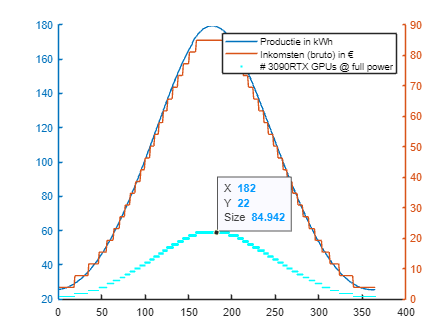

datatip(x3090RTXGPUsFullPower,182,791);

## Created by Joachim Snellings

% e-mail: snellingsjoachim@hotmail.com
% Created: 25.03.2022;
% Last update: 10.01.2024